This script solves HW 3.

**Problem 1**

Part 1a


$$G(s) = \frac{-s+3}{\left(s+2\right)\left(s+1000\right)$$


s = tf('s');
G1 = (-s+3)/(s+2)/(s+1000)

G1 =
 
        -s + 3
  -------------------
  s^2 + 1002 s + 2000
 
Continuous-time transfer function.



G1_d = G1*exp(-.005*s)

G1_d =
 
                        -s + 3
  exp(-0.005*s) * -------------------
                  s^2 + 1002 s + 2000
 
Continuous-time transfer function.



The desired loopshape must contain the unstable zero as well as the time delay.  Let's maximize the crossover such that we get the desired margins.  Note that I am separating $a$ and $b$ so that I get roughly the maximum phase lead out of the desired loop shape.

wc = .1;
GM = 100;
PM = 100;
L_d_nodelay = 0;
while(GM>2 & PM>40)
    L_old = L_d_nodelay;
    L_d = (s+.1*wc)/s^2/(s+10*wc)*exp(-.005*s)*(-s+3)/(s+3);
    [mag,phase] = bode(L_d,wc);
    L_d = L_d/mag;
    L_d_nodelay = (s+.1*wc)/s^2/(s+10*wc)*(-s+3)/(s+3)/mag;
    [GM,PM,junk1,junk2] = margin(L_d);    
    wc = wc+.1;
end

Now we have found the loop shape that best meets the specs.  Finding the controller is the easy part.

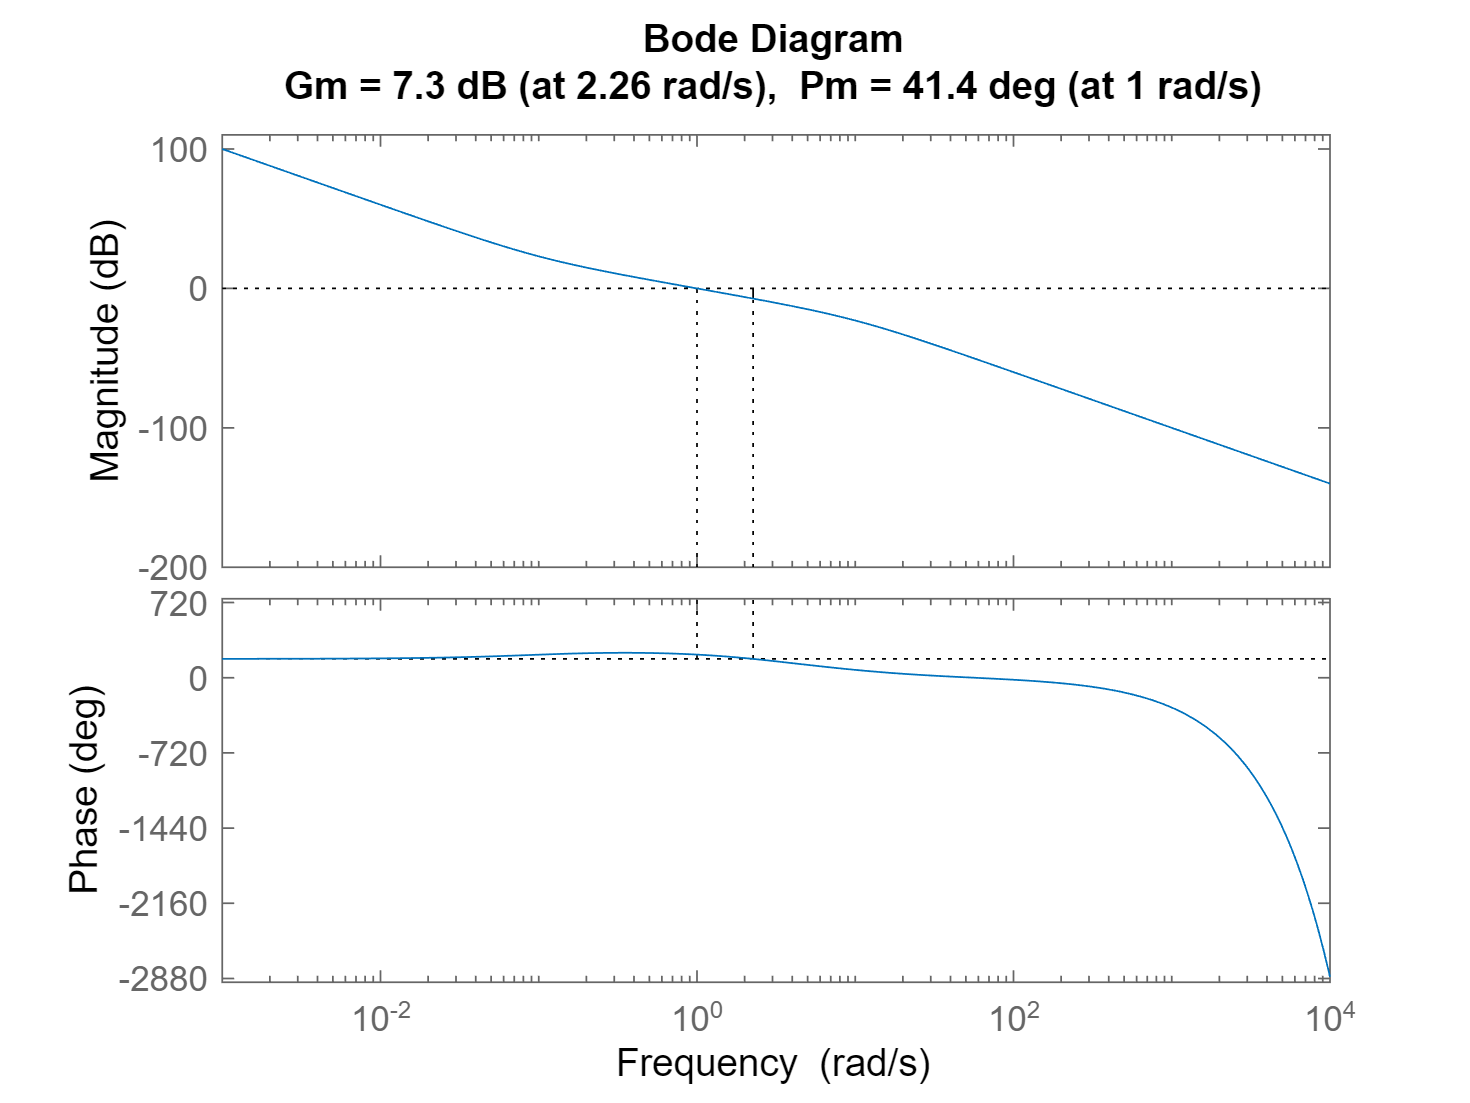

K = minreal(L_old/G1);
L = G1_d*K;
margin(L)

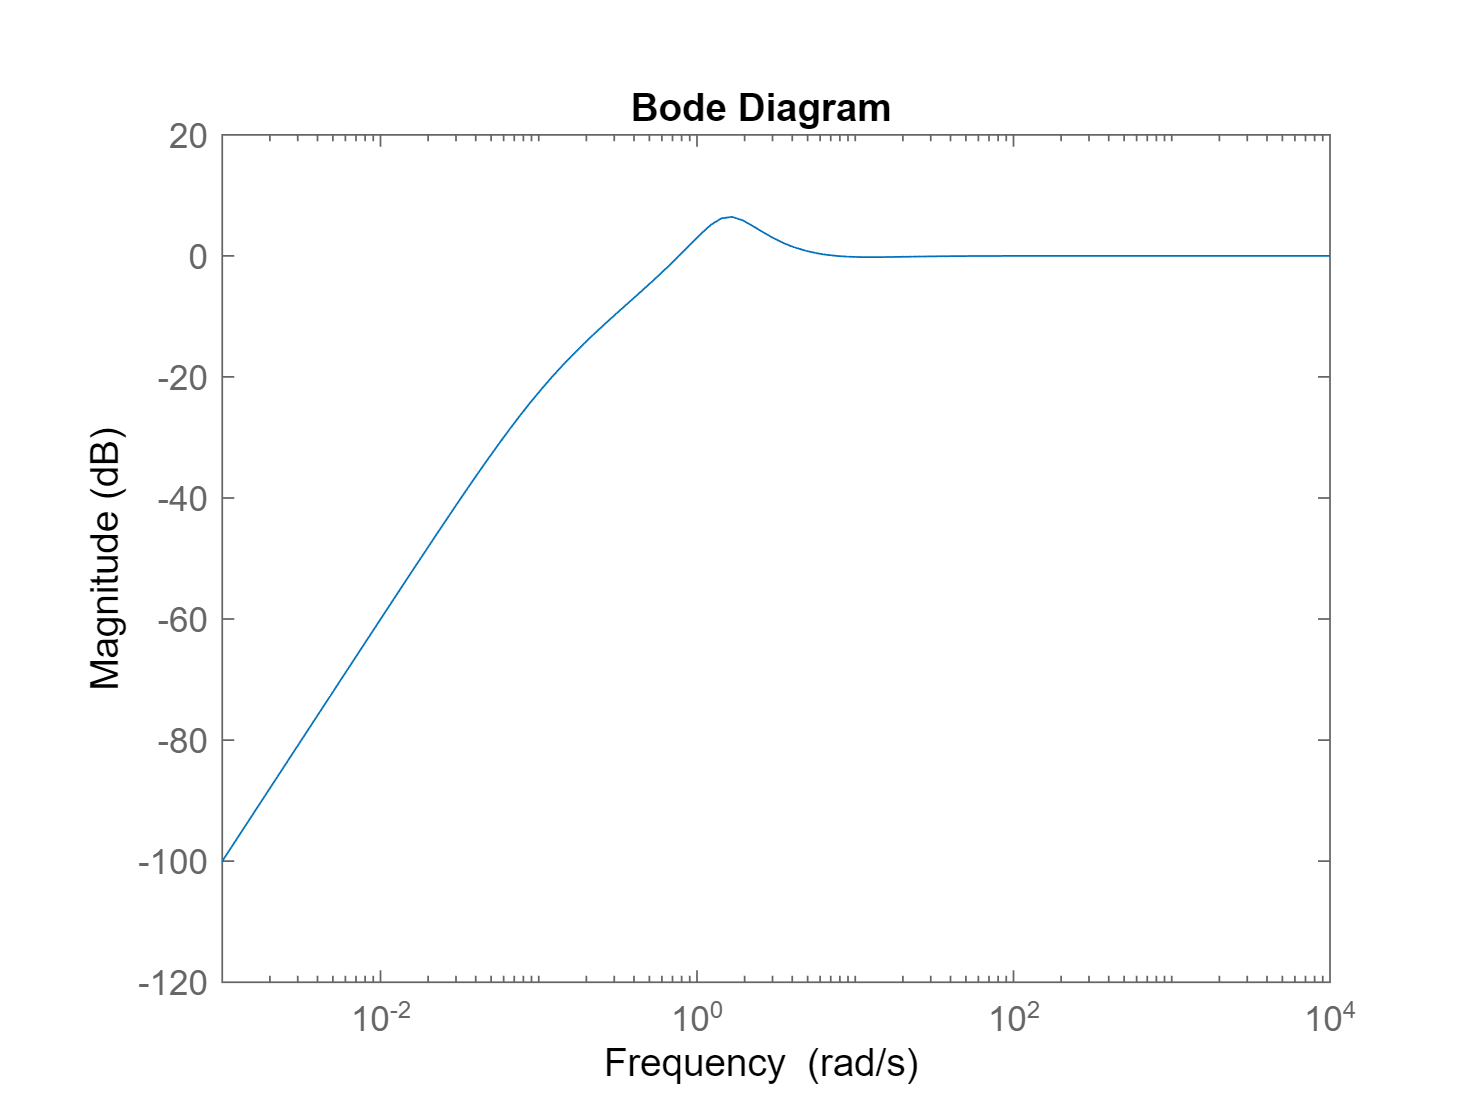

bodemag(1/(1+L))

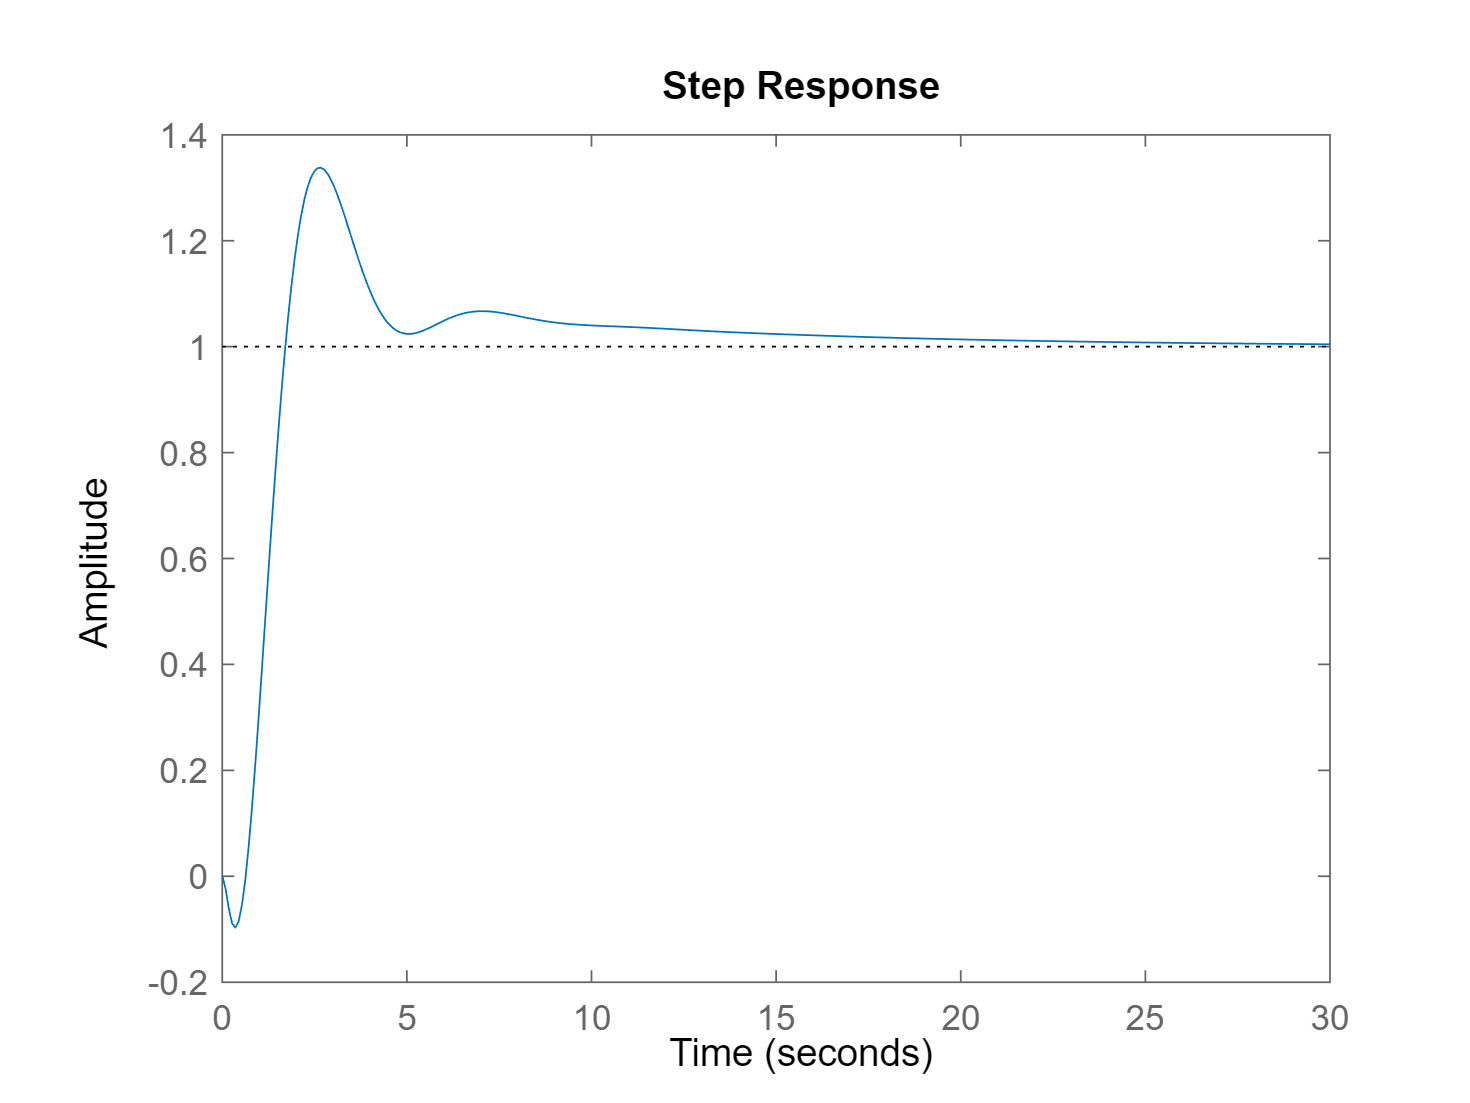

step(1-1/(1+L))

The performance is not very good, and as we will see, is fundamentally limited by the location of the non-minimum phase zero.

Part 1b


$$G(s) = \frac{s+5}{\left(-s+1\right)\left(s+1000\right)$$


I'm just going to synthesis this.  I'll shoot for a sensitivity crossover of about 700 rad/s to get the desired open loop crossover, and bound the sensitivity peak at 2 to get the required margins.

G2 = (s+5)/(-s+1)/(s+1000);
M = 2;  %Maximum sensitivity peak - for sure meets specs
A = 0.1;  %Low frequency attenuation
BW = 700;
Wp = 1/makeweight(A,BW,M);  %First order weight

Now perform the design.

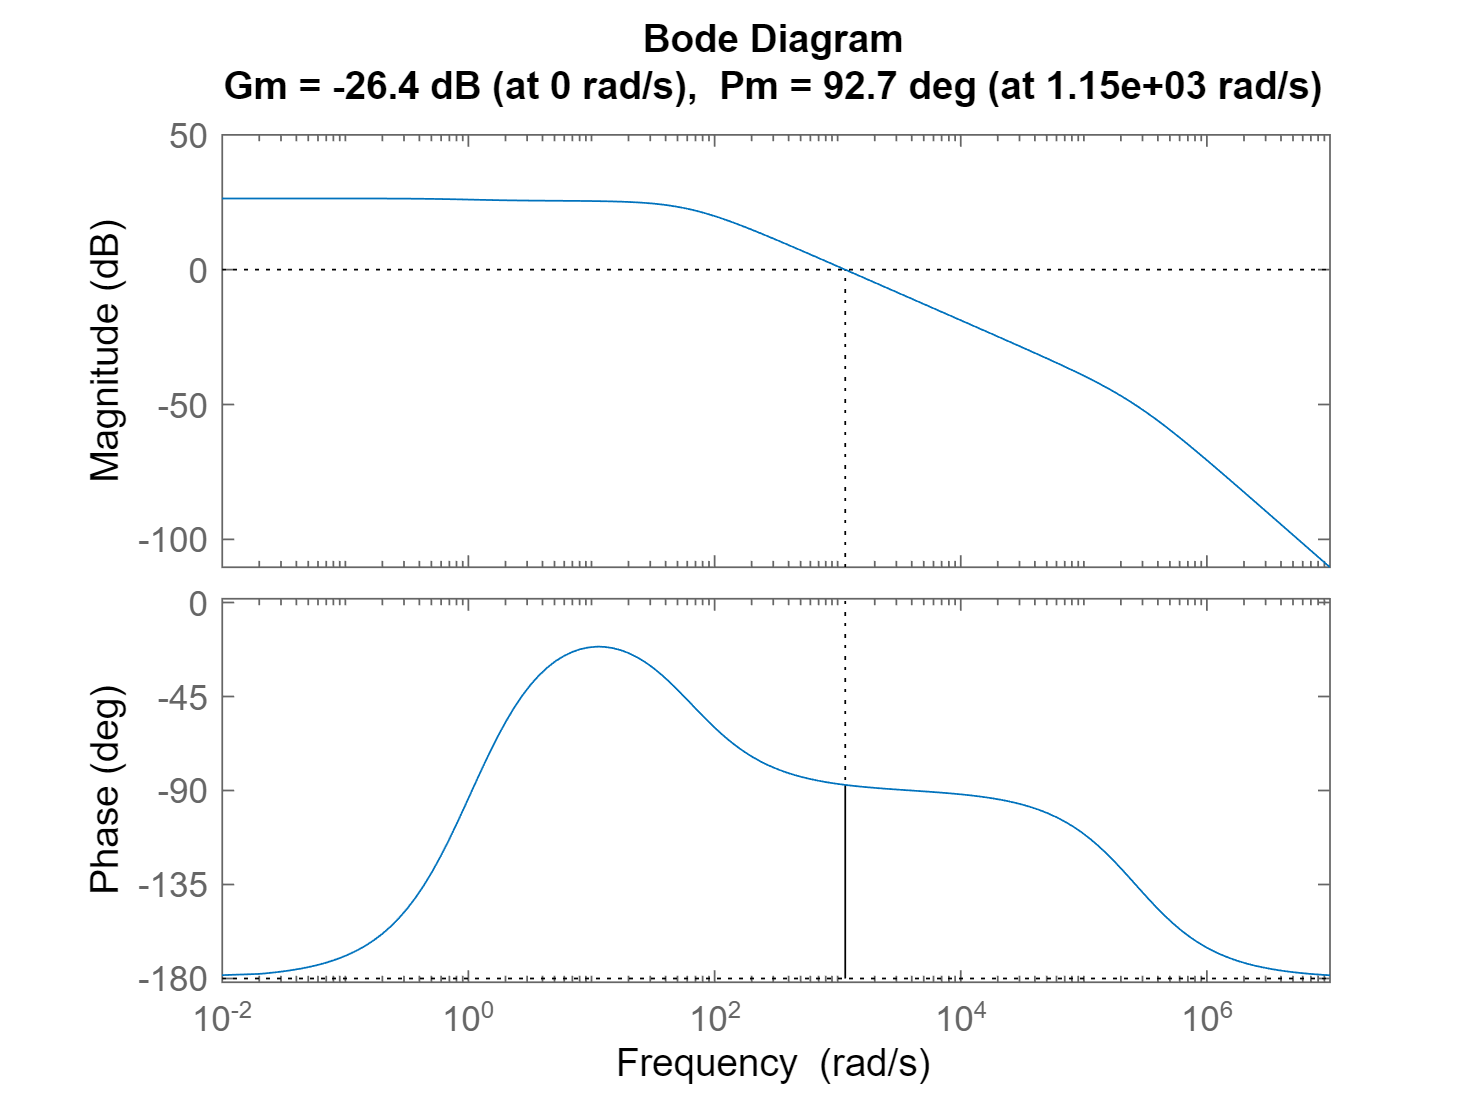

[K,CL,GAM,info] = mixsyn(G2,Wp,[],[]);
L = G2*K;
margin(L)

For this open loop unstable system, we need to reinterpret the stability margins presented by Matlab.  It's trivial to check that the closed loop system is stable, and therefore the GM and PM reported are valid.  It turns out the specs were trivial to achieve!  In fact, we could get whatever bandwidth we want out of this system (with no uncertainty).

Now for the sensitivity function

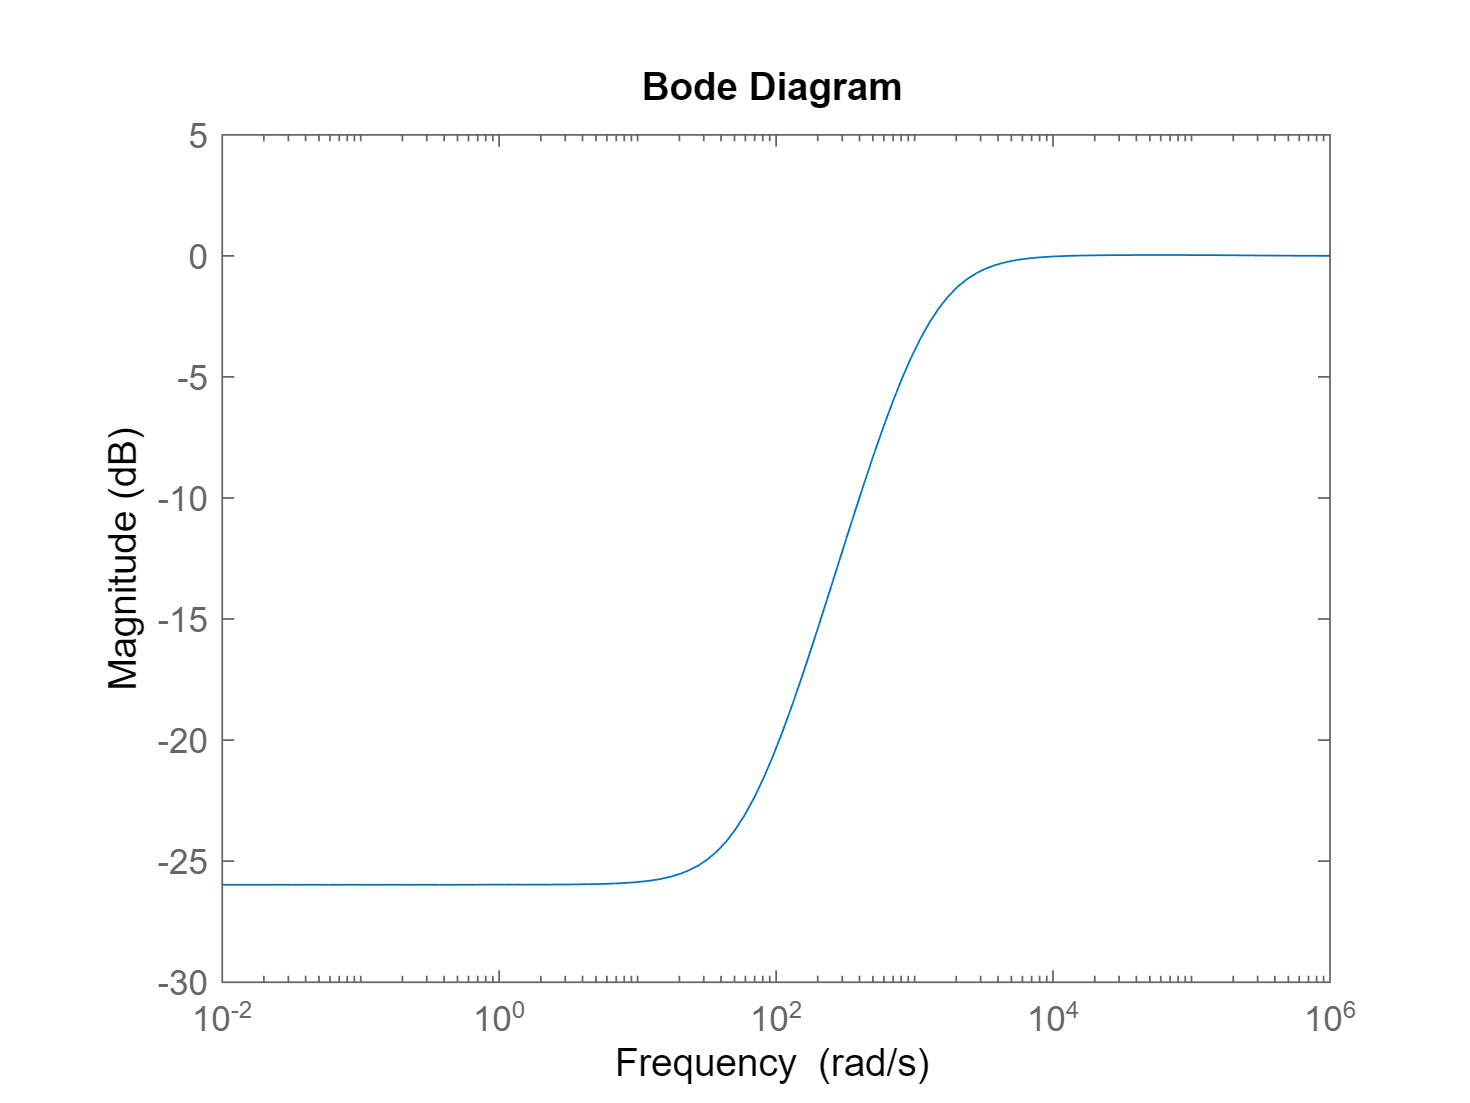

S = 1/(1+L);
bodemag(S)

**Problem 2**

SISO Mixed Sensitivity Synthesis

Part 2a

Get the model into the workspace.

HDDModel;

Start with a design for a first order weight.  I'll use *makeweight* for this one.

M = 2;  %Maximum sensitivity peak - not a bad general rule of thumb
A = 0.001;  %Low frequency attenuation
BW = 3000*2*pi;
Wp1 = 1/makeweight(A,BW,M);  %First order weight

Now build a 2nd order sensitivity weight that achieves the desired goals.

Wp2 = (s/sqrt(M)+BW)^2/(s+BW*sqrt(A))^2;  %Generate 2nd order weight

With the weights defined, we can do the synthesis.

[K1,CL,GAM1,info] = mixsyn(P,Wp1,[],[]);
[K2,CL,GAM2,info] = mixsyn(P,Wp2,[],[]);
GAM1  %Check success of design

GAM1 = 0.5826

GAM2

GAM2 = 0.6896

The design was a success!

Now make the required plots:

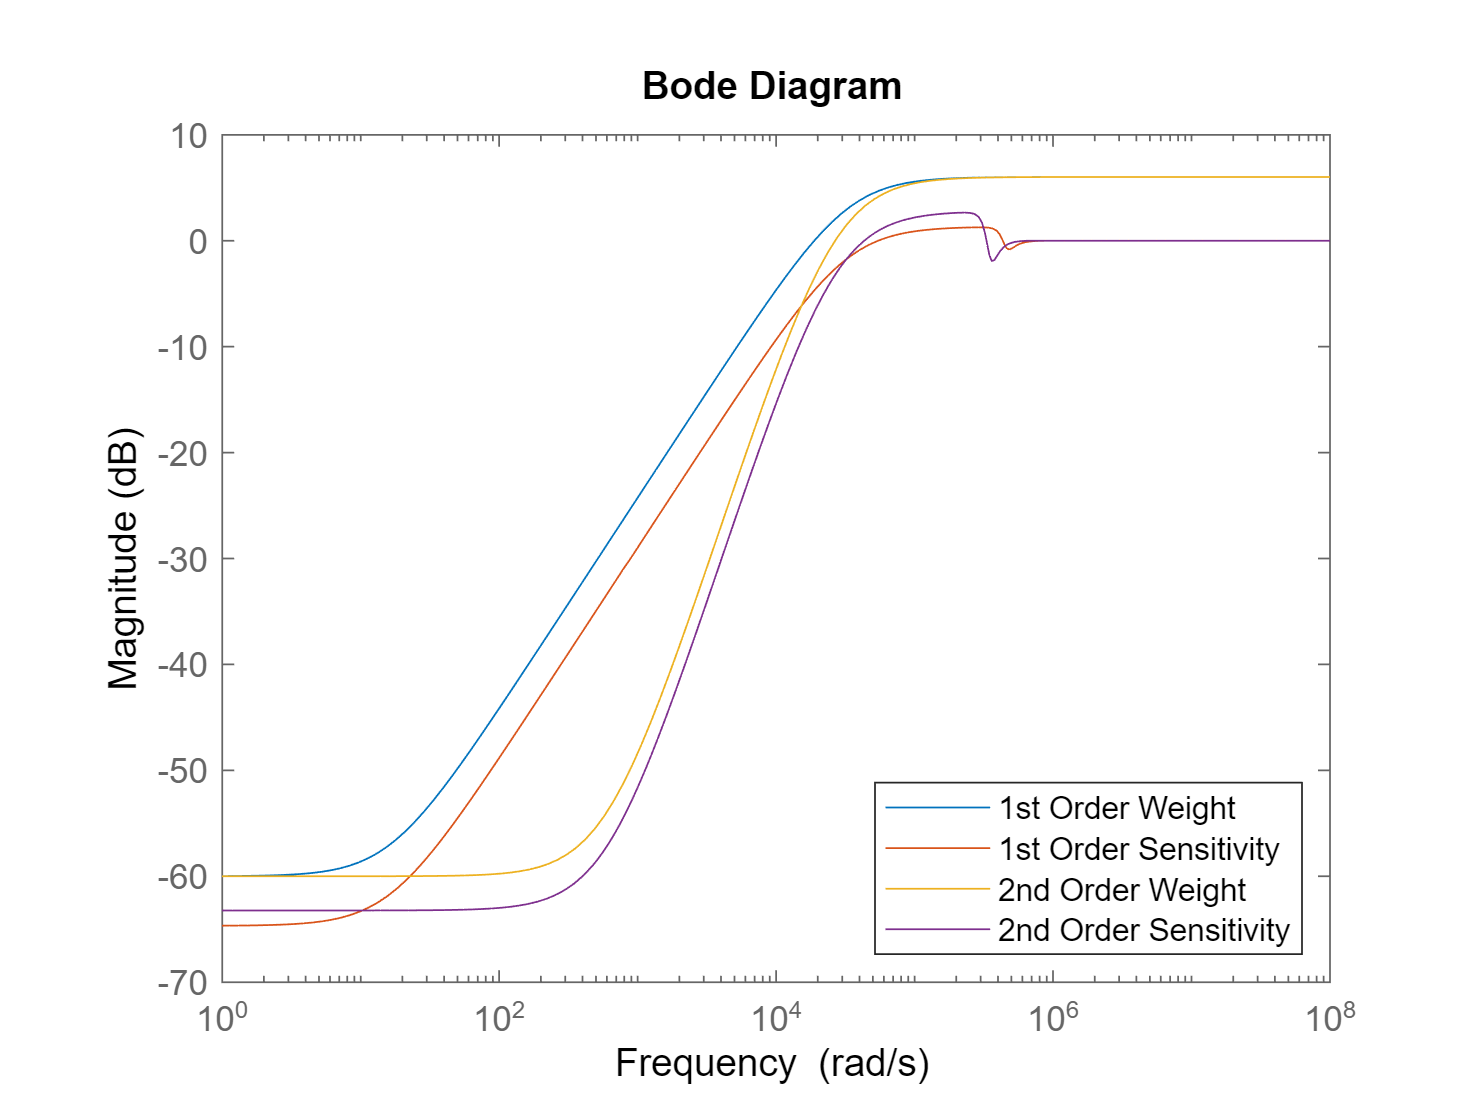

S1 = 1-feedback(P*K1,1);
S2 = 1-feedback(P*K2,1);
bodemag(1/Wp1,S1,1/Wp2,S2)
legend('1st Order Weight','1st Order Sensitivity','2nd Order Weight','2nd Order Sensitivity','Location','southeast')

Both designs trivially achieve the goals.

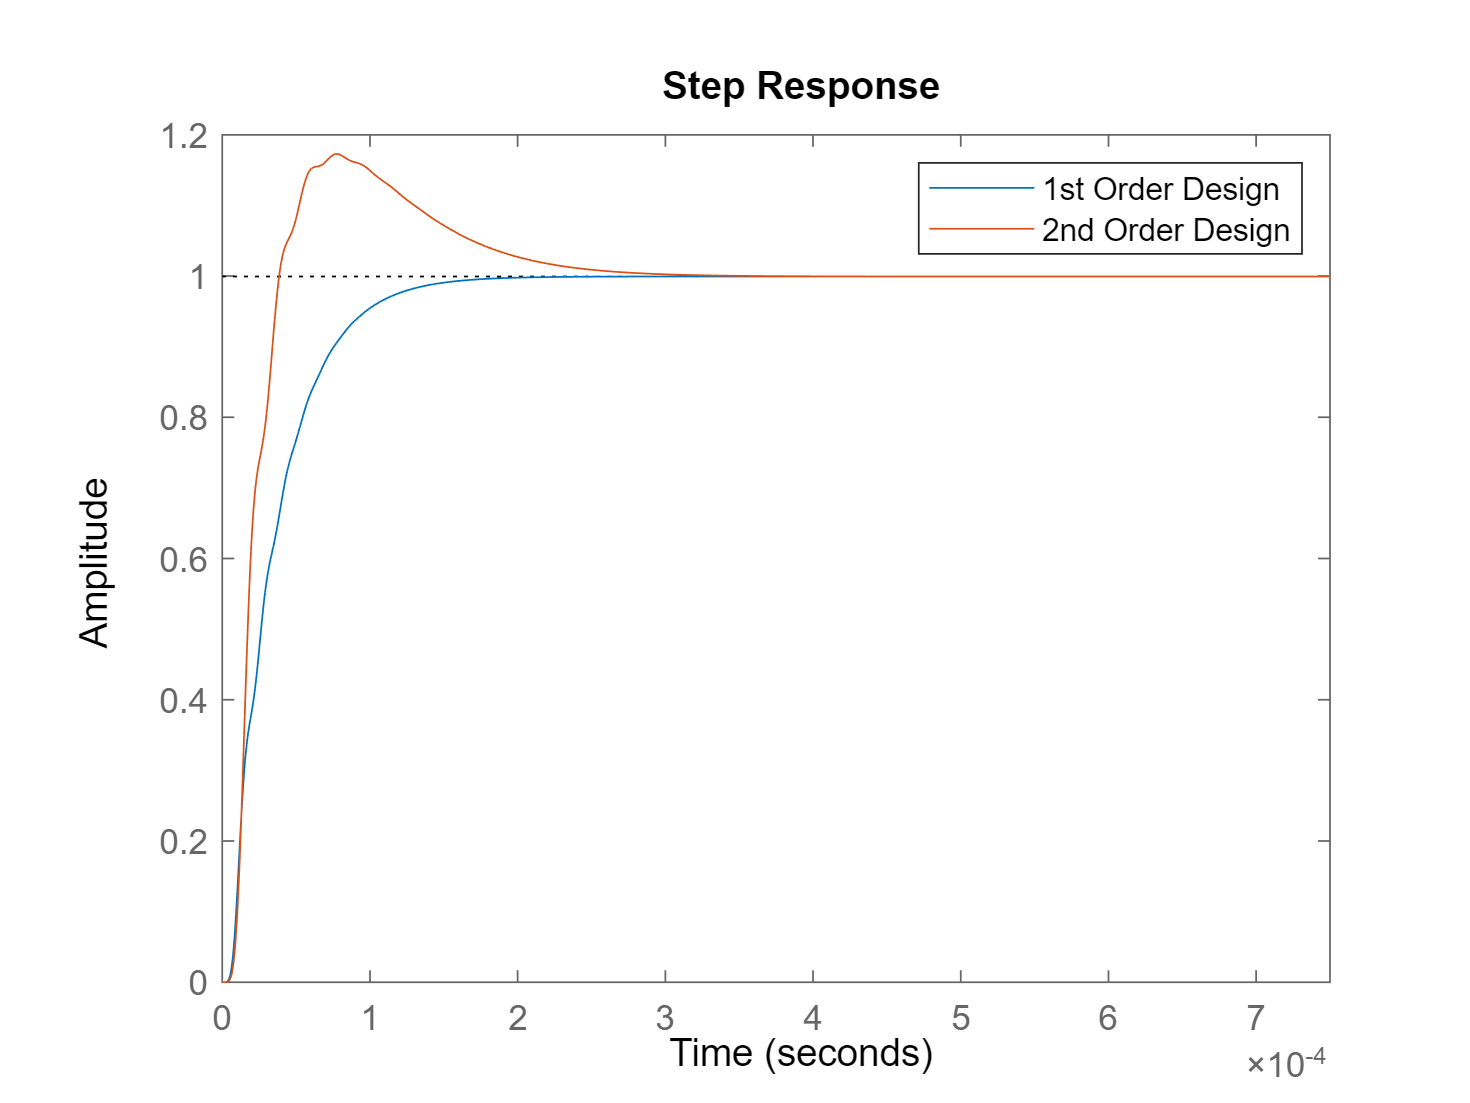

step(1-S1,1-S2,.75e-3)
legend('1st Order Design','2nd Order Design')

Are we limited?  A bit.  For instance:

BW = 1e6;
Wphigh = (s/sqrt(M)+BW)^2/(s+BW*sqrt(A))^2;  %Generate 2nd order weight
[Khigh,CL,GAMhigh,info] = mixsyn(P,Wphigh,[],[]);
GAMhigh

GAMhigh = 110.4908

Part 2b

If we give the complementary sensitivity function the same crossover frequency as the performance weight, we will not meet the compatibility requirement - the crossover of T should be higher than that of S.  I'll choose a 1st order weight, this time using *makeweight.  *Note that for a realizable weight I can't actually force the high frequency rolloff forever (would need a single zero).

WT = 1/makeweight(2,10000*2*pi,1e-3);

Now that we have compatible weights, we can proceed with the design.

[K,CL,GAM,info] = mixsyn(prescale(ss(P)),Wp2,[],WT);
GAM

GAM = 1.2392

This time we didn't make it, but it's close.

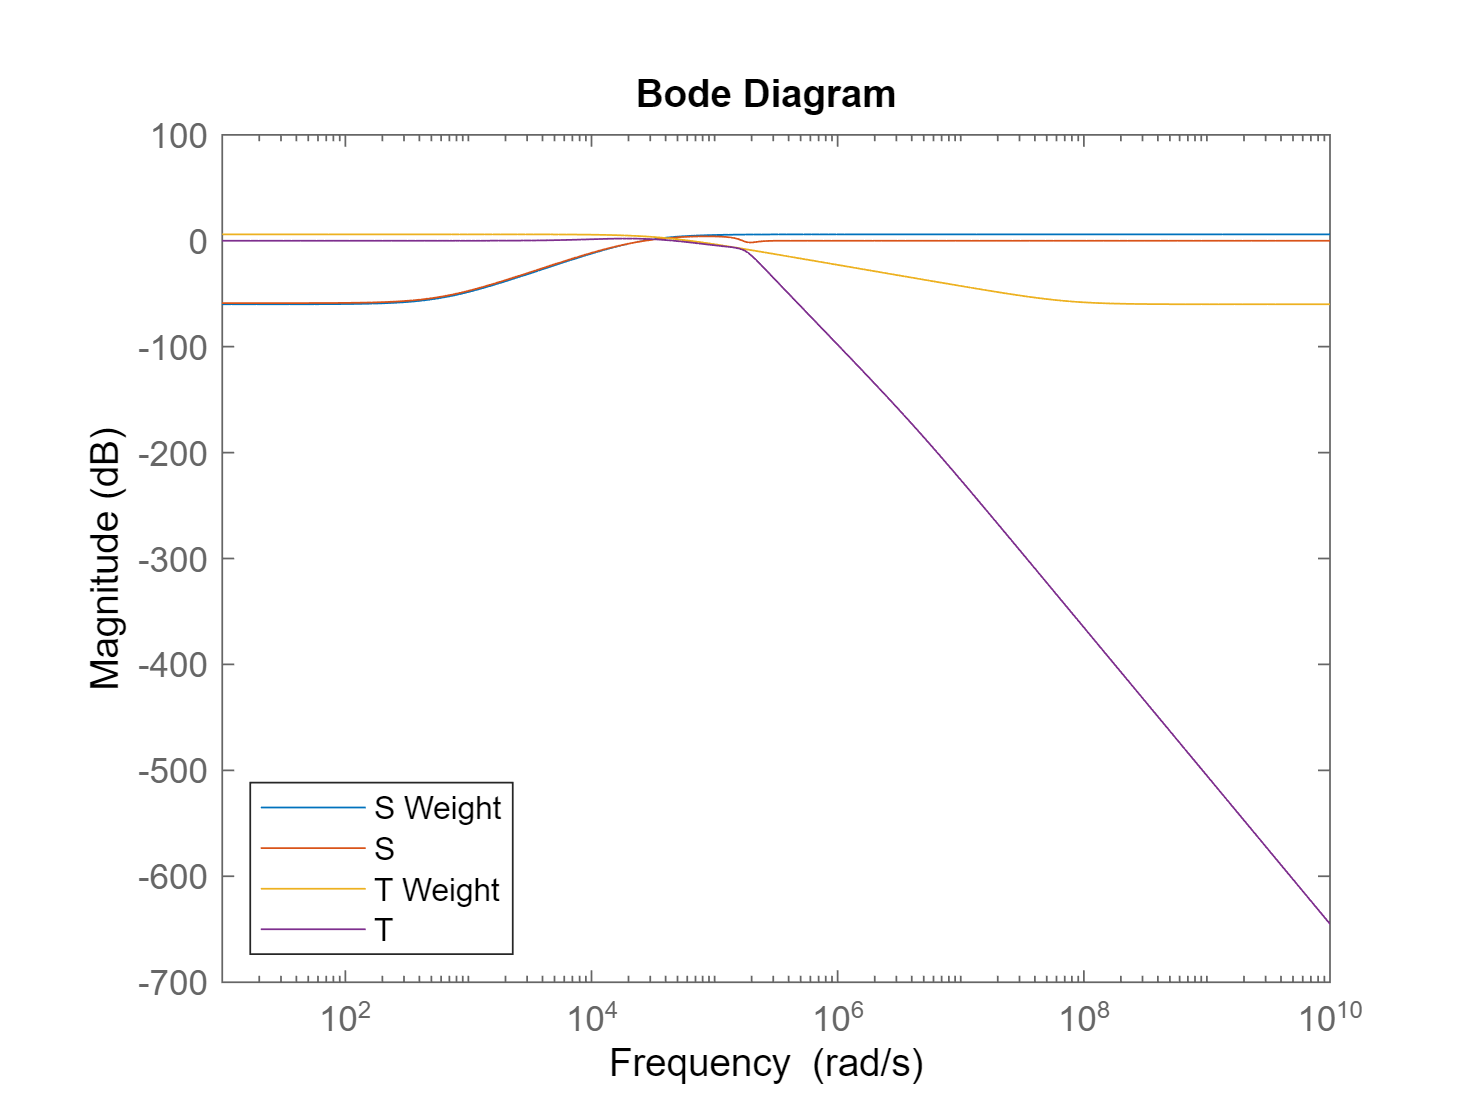

T = feedback(P*K,1);
S = 1-T;
bodemag(1/Wp2,S,1/WT,T)
legend('S Weight','S','T Weight','T','Location','southwest')

S_inf = norm(Wp2*S,'inf')

S_inf = 1.1341

T_inf = norm(WT*T,'inf')

T_inf = 0.9769

Part 2c

Finally, we'll add a control weight and complete the design.  For this design we're told that the saturation level is at an input of 100, so we'll make the weight the inverse of that.

Wu = 1/100;
BW = 100;
GAM = 0;
Wp = 0;
while (GAM<1)
    Wp_old = Wp;
    WT_old = WT;
    K_old = K;
    GAM_old = GAM;
    Wp = (s/sqrt(M)+BW)^2/(s+BW*sqrt(A))^2; 
    WT = 1/makeweight(2,5*BW,1e-3);
    [K,CL,GAM,info] = mixsyn(ss(P),Wp,Wu,WT);  
    BW = BW+10;
end

Now let's compute the norm and make some plots.  I guess we should also check the bandwidth.

Final_Bandwidth = BW-10

Final_Bandwidth = 2990

T = feedback(P*K_old,1);
S = 1-T;
H_inf = norm([Wp_old*S;Wu*K_old*S;WT*T],'inf')

H_inf = 0.9912

GAM_old

GAM_old = 0.9912

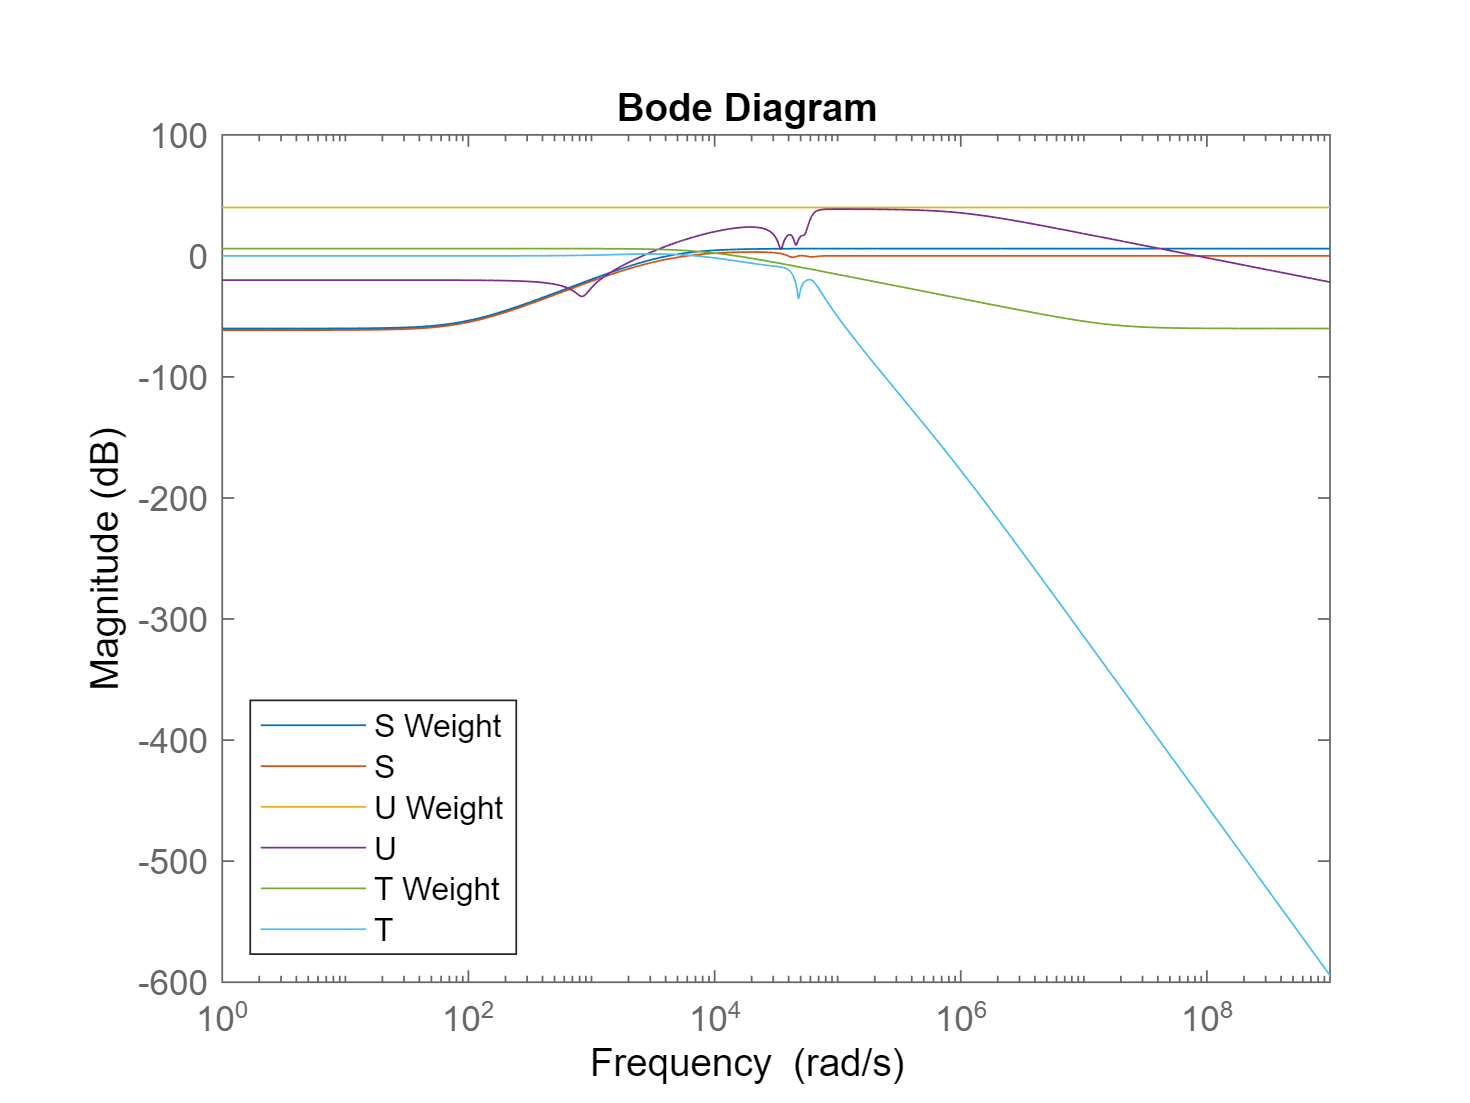

bodemag(1/Wp_old,S,tf(1/Wu,1),K_old*S,1/WT_old,T)
legend('S Weight','S','U Weight','U','T Weight','T','Location','southwest')

**Problem 3**

Part 3a

Our job now is to include the 2nd stage actuator.  It must be that the product $L = GK$must be 1 by 1 for this system, which implies that 

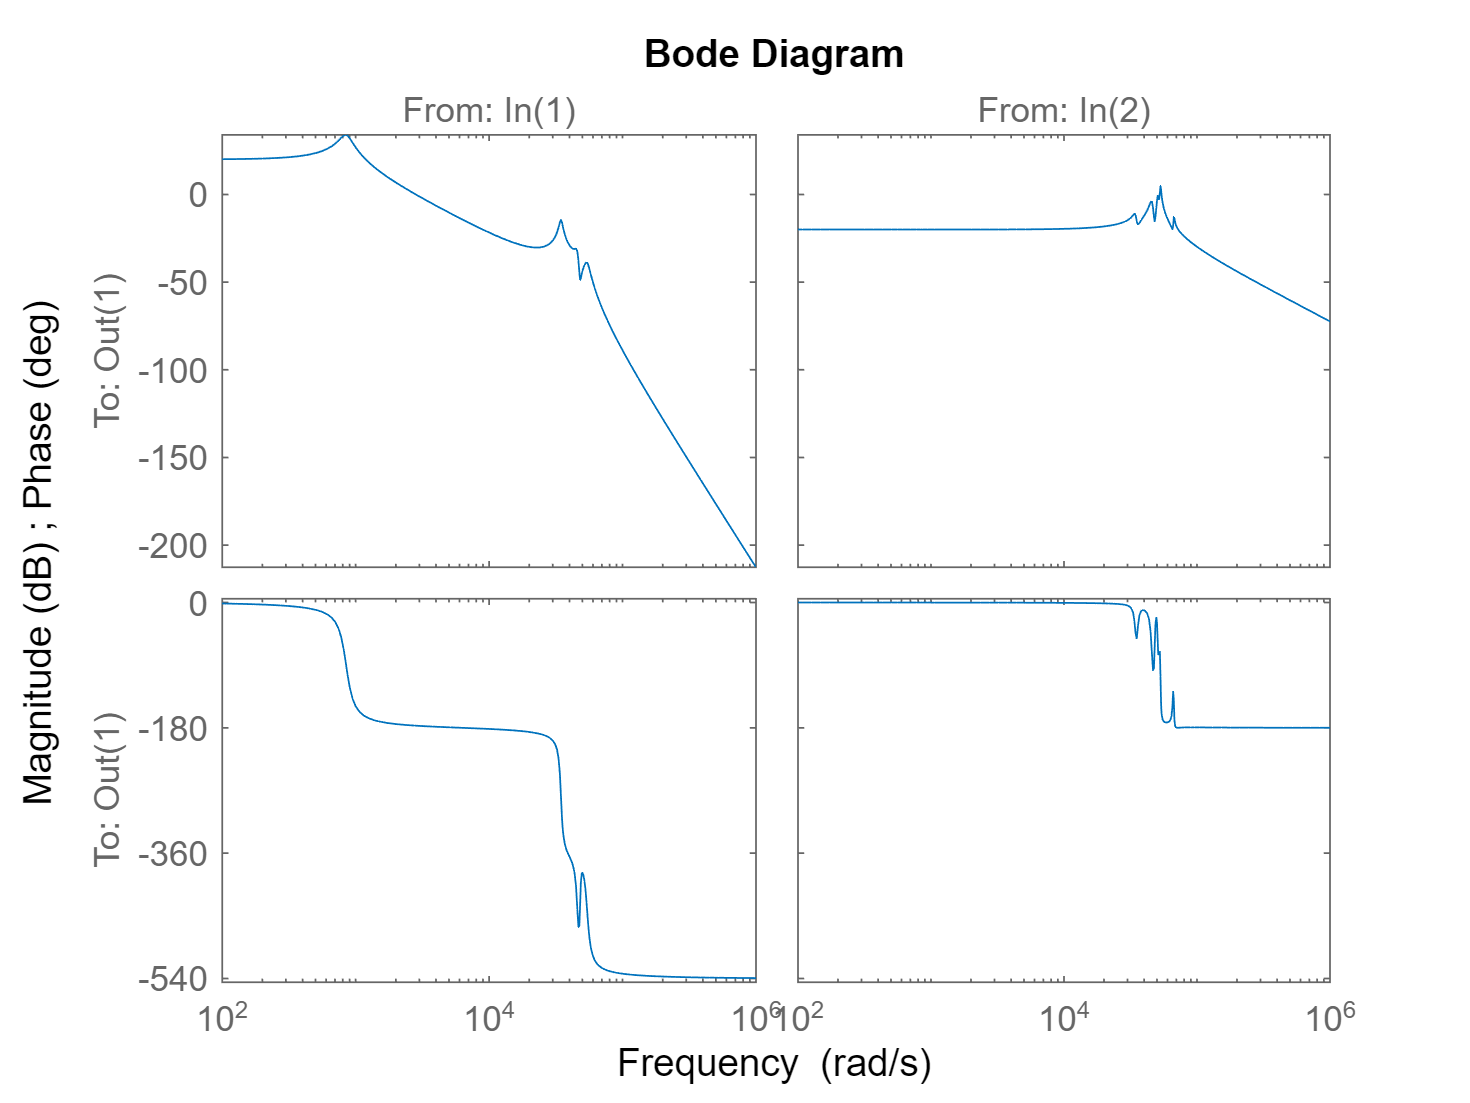

HDDModel_DS;
G = [VCM PZT];
bode(G)

From the plot, the big benefit of the 2nd stage system is the near-zero phase up to 20000 rad/s or so.  As we will see later, this will be critical once uncertainty comes into play.

Part 3b

First we have to build the controller weight.  Here it is a 2-by-2 matrix of constants.

Wu = diag([1/100 1/10]);

Now build the performance weight and perform the synthesis.

BW = 3000;
GAM = 0;
Wp = 0;
while (GAM<1)
    Wp_old = Wp;
    WT_old = WT;
    K_old = K;
    GAM_old = GAM;
    Wp = (s/sqrt(M)+BW)^2/(s+BW*sqrt(A))^2; 
    WT = 1/makeweight(2,5*BW,1e-3);
    [K,CL,GAM,info] = mixsyn(G,Wp,Wu,WT);
    BW = BW+10;
end
Final_Bandwidth = BW-10

Final_Bandwidth = 3870

GAM_old

GAM_old = 0.9995

Find the closed loop transfer functions and plot the results.

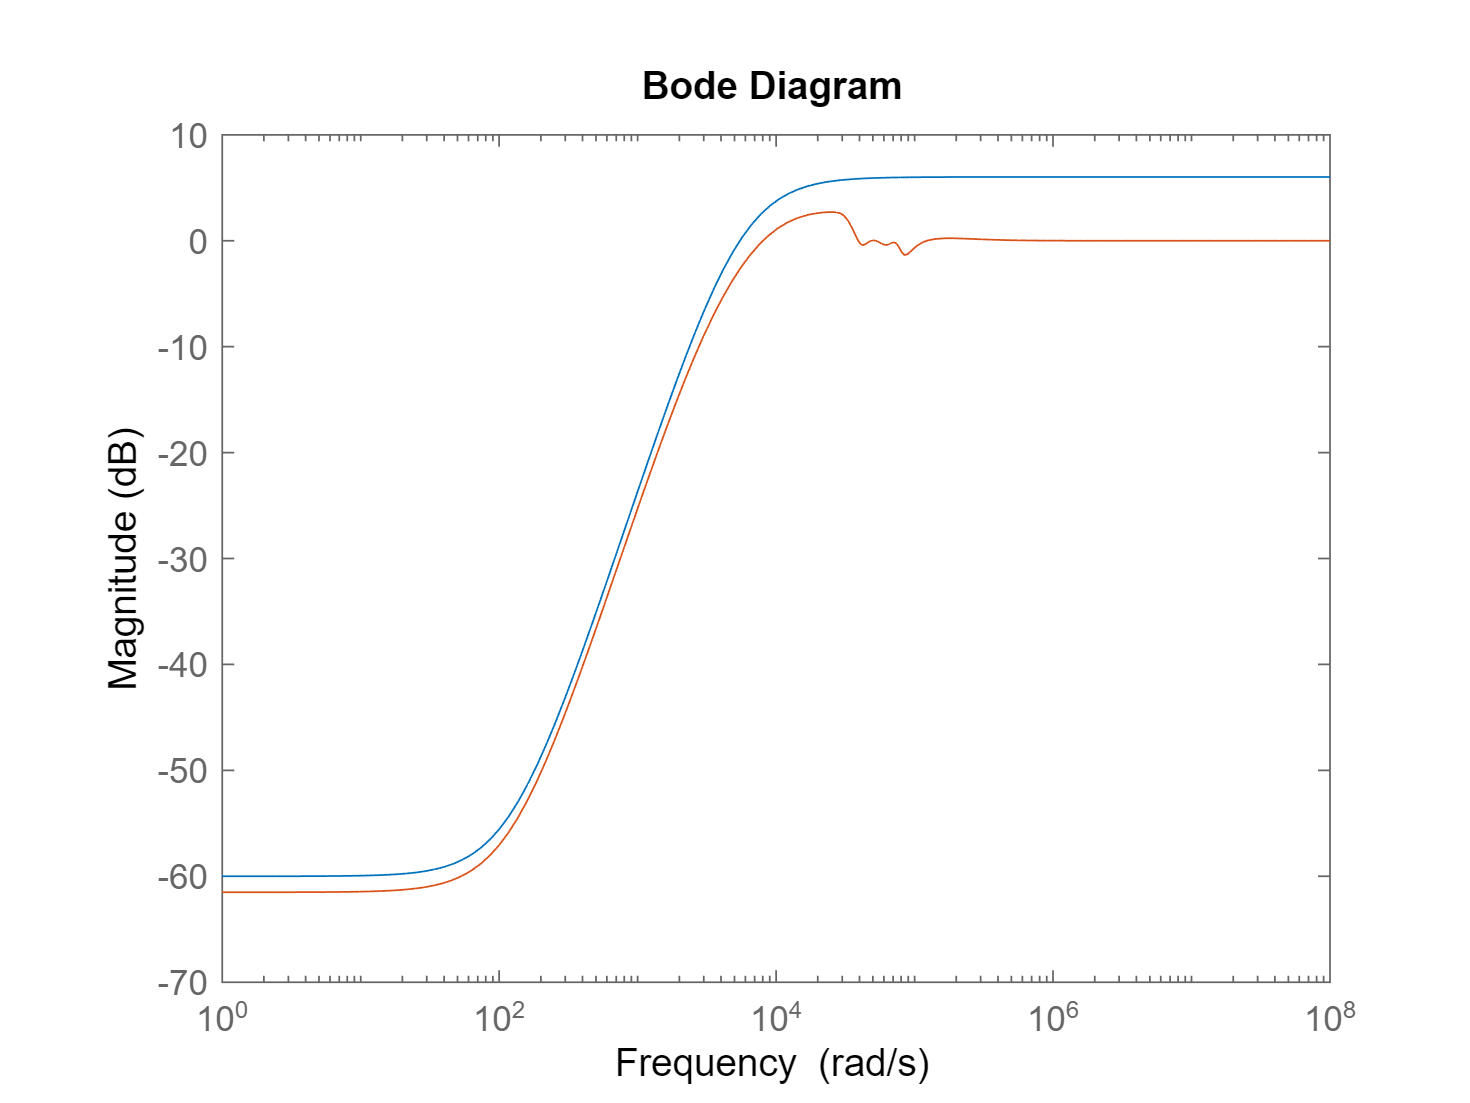

T = feedback(G*K_old,1);
S = 1-T;
bodemag(1/Wp,S)  %The performance plot

Clearly the design meets the goal, as $\gamma$ would show.

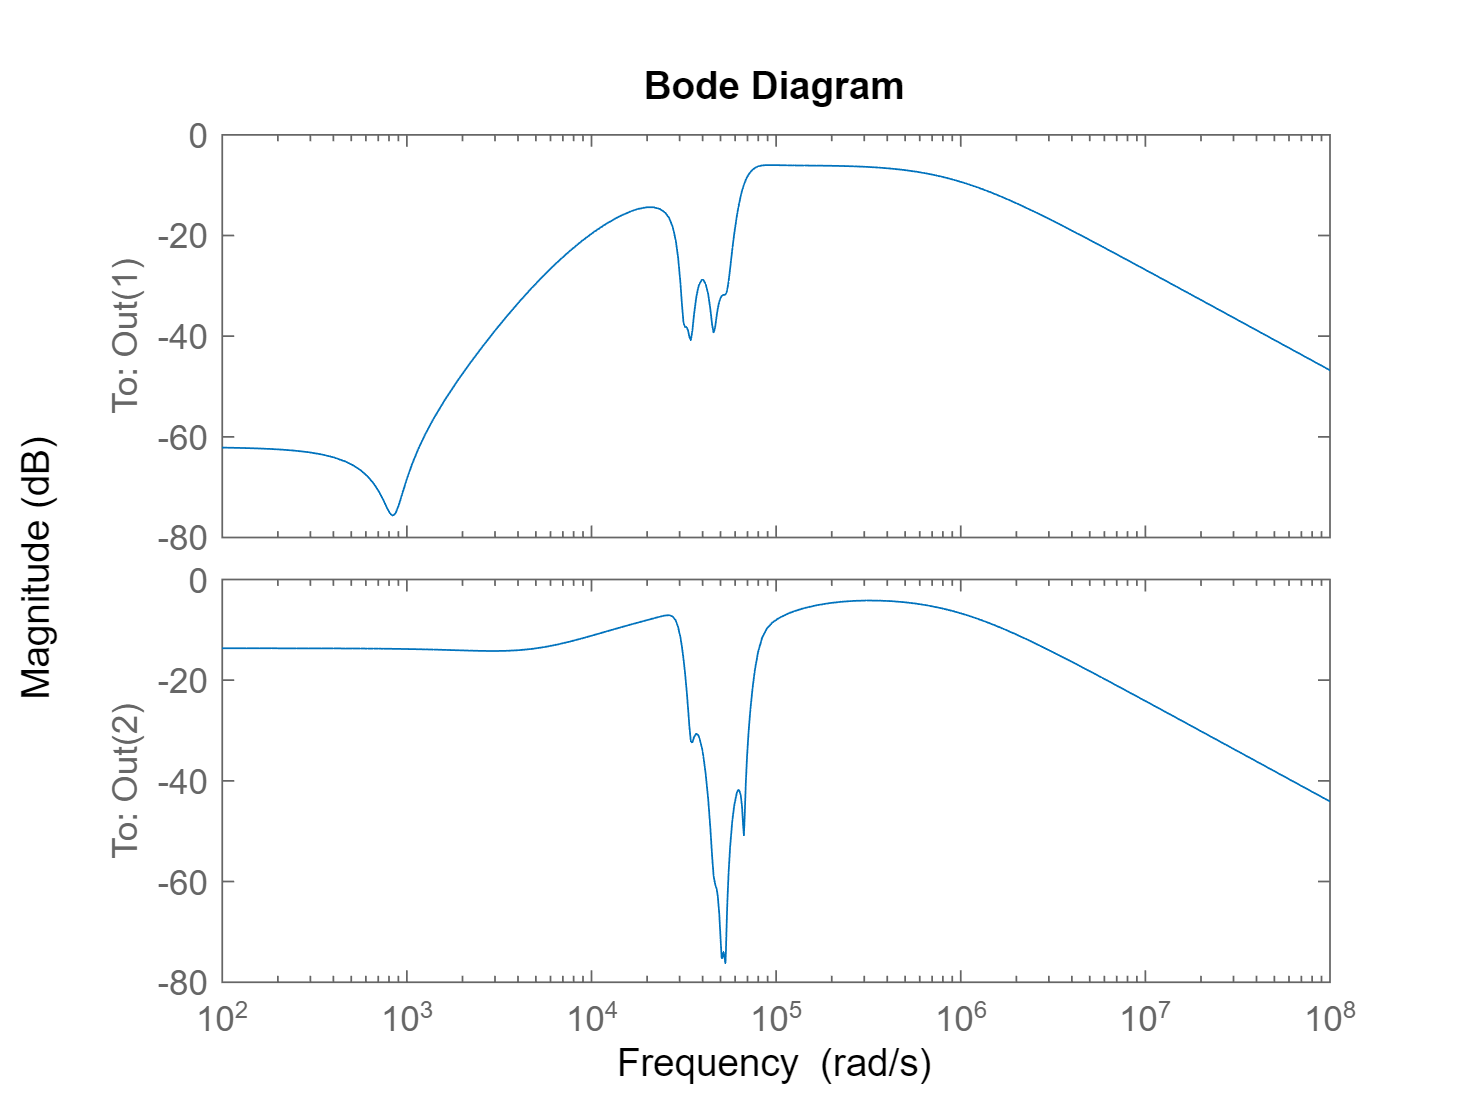

bodemag(Wu*K_old*S);

By weighting the two transfer functions differently we can clearly control the relative control effort.  However, it is also clear that use of the infinity norm bound is not a good replacement for an absolute magnitude constraint, i.e., I can easily find an input that pushing the usage above the bounds.